The previous model with logistic growth can be adpated to use predator feeding limits, leading to the Holling Type 2 model, given by


$$\frac{dx_1}{dt}=a x_1\left (1-\frac{x_1}{K}\right) - \frac{b x_1}{1+bhx_1}x_2 \\ \frac{dx_2}{dt}=c  \frac{b x_1 }{1+bhx_1}x_2 - d x_2 $$


where $a,b,c,d,h,K$ are real constants. The FunctionalResponse script inside the Models folder will return a function handle for the ODE. Note how predator efficiency is set to be much higher now to avoid extintion, due to functional response greatly limiting the reproduction rate.

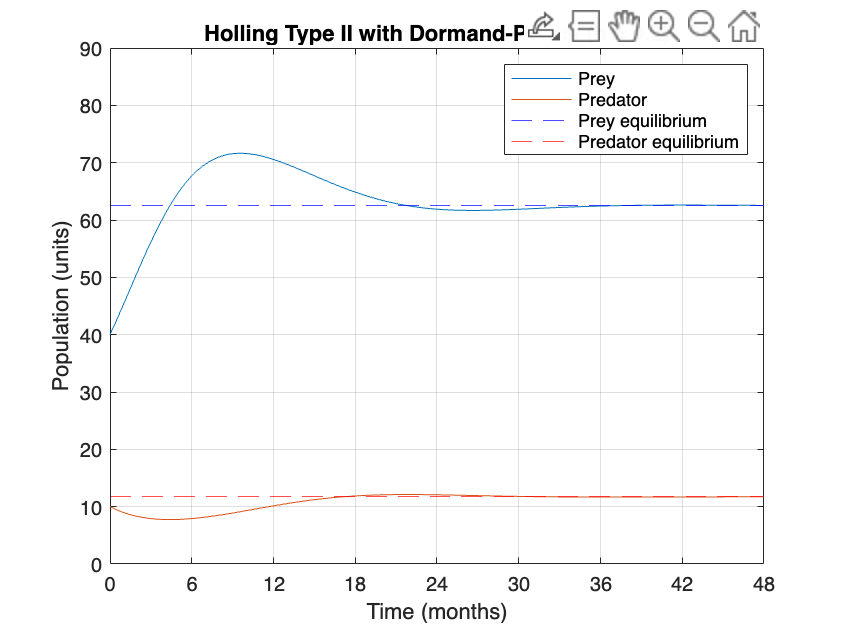

a = 0.5;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.4;  % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey
K = 100;  % Carrying capacity
h = 0.2;  % 6 days to chase, hunt and eat prey

prey = 40; predator = 10; n = 1000; t_end = 48;

f = FunctionalResponse(a,b,c,d,h,K);

[t,x] = DormandPrince(f, 0, t_end, [prey; predator], n);
plot(t,x)
grid

pred_eq = -a*c*(d-b*c*K+b*d*h*K)/(b^2*(c-d*h)^2*K);
prey_eq = d/(b*(c-h*d));

yline(prey_eq, "--",Color="b");
yline(pred_eq, "--",Color="r");
legend("Prey","Predator","Prey equilibrium","Predator equilibrium",location="northeast")
title("Holling Type II with Dormand-Prince (h = " + h + ")")

xlim([0 48])
ylim([0 90])
xticks(0:6:48)
ylabel("Population (units)")
xlabel("Time (months)")